#### 
$$\mathbf{f}\left(t,\mathbf{y}\right)=\left\lbrack \begin{array}{c}
-y\left(1\right)+y\left(2\right)\\
-y\left(2\right)
\end{array}\right\rbrack y^0 =\left\lbrack \begin{array}{c}
-2\\
-1
\end{array}\right\rbrack ,t\in \left\lbrack 0,10\right\rbrack ,h=1$$



$$\mathbf{Df}\left(t,\mathbf{y}\right)=\left\lbrack \begin{array}{cc}
-1 & 1\\
0 & -1
\end{array}\right\rbrack$$



$$\mathbf{f}\left(t,\mathbf{y}\right)=\left\lbrack \begin{array}{c}
e^{-x} +e^{-x} x\\
e^{-x} 
\end{array}\right\rbrack$$



$${\mathbf{y}}^{\left(i+1\right)} ={\mathbf{y}}^{\left(i\right)} +h\;\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(i+1\right)} \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;$$



$${\mathbf{y}}^{\left(i+1\right)} ={\mathbf{y}}^{\left(i\right)} +h\;\left\lbrack \begin{array}{c}
-y_1^{\left(i+1\right)} +y_2^{\left(i+1\right)} \\
-y_2^{\left(i+1\right)} 
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;$$


(i = 0)


$${\mathbf{y}}^{\left(1\right)} =\left\lbrack \begin{array}{c}
-2\\
-1
\end{array}\right\rbrack +\;\left\lbrack \begin{array}{c}
-y_1^{\left(1\right)} +y_2^{\left(1\right)} \\
-y_2^{\left(1\right)} 
\end{array}\right\rbrack =\;\left\lbrack \begin{array}{c}
-2-y_1^{\left(1\right)} +y_2^{\left(1\right)} \\
-1-y_2^{\left(1\right)} 
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;$$



$${\mathbf{z}}^{\left(i+1\right)} ={\mathbf{z}}^{\left(i\right)} -\frac{{\mathbf{f}}^{\left(i\right)} }{{{\mathrm{D}}_z \mathbf{f}}^{\left(i\right)} }\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(c\ldotp 6\right)\;\;\;\;\;\;\;\;$$


Setzten wir nun $\mathbf{z}={\mathbf{y}}^{\left(1\right)}$ in (c.5):


$$\mathbf{z}=\left\lbrack \begin{array}{c}
-2-z_1 +z_2 \\
-1-z_2 
\end{array}\right\rbrack$$



$$\mathbf{f}\left(\mathbf{z}\right)\;=\left\lbrack \begin{array}{c}
-2-z_1 +z_2 \\
-1-z_2 
\end{array}\right\rbrack -\mathbf{z}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(c\ldotp 8\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;$$



$$\left(\mathbf{z}\right)\;=\left\lbrack \begin{array}{c}
-2-{2z}_1 +z_2 \\
-1-{2z}_2 
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(c\ldotp 8\right)$$



$${\mathrm{D}}_z \mathbf{f}\left(\mathbf{z}\right)=\left\lbrack \begin{array}{cc}
-2 & 1\\
0 & -2
\end{array}\right\rbrack$$



y0 = [-2;-1];
tol = 10^(-15);
nmax = 1000;
ti = 0;
h = 1;
[z1,fval,exitflag] = newton(@f_beispiel2, y0, tol, nmax)

z1 =   -1.250000000000000
  -0.500000000000000


fval =      0
     0


exitflag =      1



y1 = y0 + z1

y1 =   -3.250000000000000
  -1.500000000000000



f_loesung = @(x) exp(-x)+exp(-x).*x;
f_loesung2 = @(x) exp(-x);



f_loesung(1)

ans =    0.735758882342885


f_loesung2(1)

ans =    0.367879441171442



f = @(t,y) [-y(1)+y(2);y(2)];
df = @(t,y) [-1,1;0,1];
syms s_z1 s_z2;
[F_e, J_e] = F_euler([s_z1;s_z2],ti,h,y0,f,df)

$$F\_e = \left(\begin{array}{c} s_{\mathrm{z2}}-2\,s_{\mathrm{z1}}+1\\ -1 \end{array}\right)$$

J_e =     -2     1
     0     0


x = linspace(0, 10, 11)

x =      0     1     2     3     4     5     6     7     8     9    10


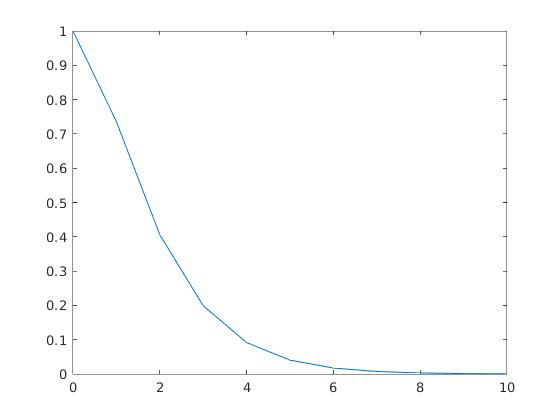


plot(x,f_loesung(x))

function [f,df] = f_beispiel2(z)
    f = [-2-2*z(1)+z(2);-1-2*z(2)];
    df = [-2,1;0,-2];
end



$${\mathbf{F}}_{\mathrm{euler}} \left(\mathbf{z}\right)=h\;\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(i\right)} +\mathbf{z}\right)-\mathbf{z}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;$$



$$\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(i\right)} +\mathbf{z}\right)=\left\lbrack \begin{array}{c}
-\left(y_1^{\left(i\right)} +z_1 \right)+y_2^{\left(i\right)} +z_2 \\
-y_2^{\left(i\right)} -z_2 
\end{array}\right\rbrack$$



$${\mathbf{F}}_{\mathrm{euler}} \left(\mathbf{z}\right)=\left\lbrack \begin{array}{c}
-y_1^{\left(i\right)} -z_1 +y_2^{\left(i\right)} +z_2 \\
-y_2^{\left(i\right)} -z_2 
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
z_1 \\
z_2 
\end{array}\right\rbrack$$



$${\mathbf{F}}_{\mathrm{euler}} \left(\mathbf{z}\right)=\left\lbrack \begin{array}{c}
-y_1^{\left(i\right)} -{2z}_1 +y_2^{\left(i\right)} +z_2 \\
-y_2^{\left(i\right)} -{2z}_2 
\end{array}\right\rbrack$$


(i = 0)


$${\mathbf{F}}_{\mathrm{euler}} \left(\mathbf{z}\right)=\left\lbrack \begin{array}{c}
-y_1^{\left(0\right)} -{2z}_1 +y_2^{\left(0\right)} +z_2 \\
-y_2^{\left(0\right)} -{2z}_2 
\end{array}\right\rbrack$$



$${\mathbf{F}}_{\mathrm{euler}} \left(\mathbf{z}\right)=\left\lbrack \begin{array}{c}
-{2z}_1 +z_2 \\
-1-{2z}_2 
\end{array}\right\rbrack$$



$${\mathbf{F}}_{\mathrm{euler}} \left(\mathbf{z}\right)=\left\lbrack \begin{array}{c}
-{2z}_1 +z_2 \\
-1-{2z}_2 
\end{array}\right\rbrack$$



$${\Rightarrow D\;\mathbf{F}}_{\mathrm{euler}} \left(\mathbf{z}\right)=\left\lbrack \begin{array}{cc}
-2 & 1\\
0 & -2
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;$$
